# Payload Carrying Quad Rotor Drone Optimization

## Project purpose:

We set our payload goal as 70 lbs because that is the maximum standard parcell weight carried by the USPS, in order to ground the project in a real world operating condition.

## Understanding thrust relationships in dynamic and static conditions:

We initially started off by trying to understand the relationships between propellor RPM, thrust generated, and incoming airstream velocity to build towards being able to simulate dynamic flight conditions.

Good quality [data on propellor performance](https://www.apcprop.com/technical-information/performance-data/?v=7516fd43adaa) that included this information was obtained from APC Propellors, a company that makes propellors for drones/model aircraft as well as marine applications, and we built a function to read in their data files and plot the relevant information.

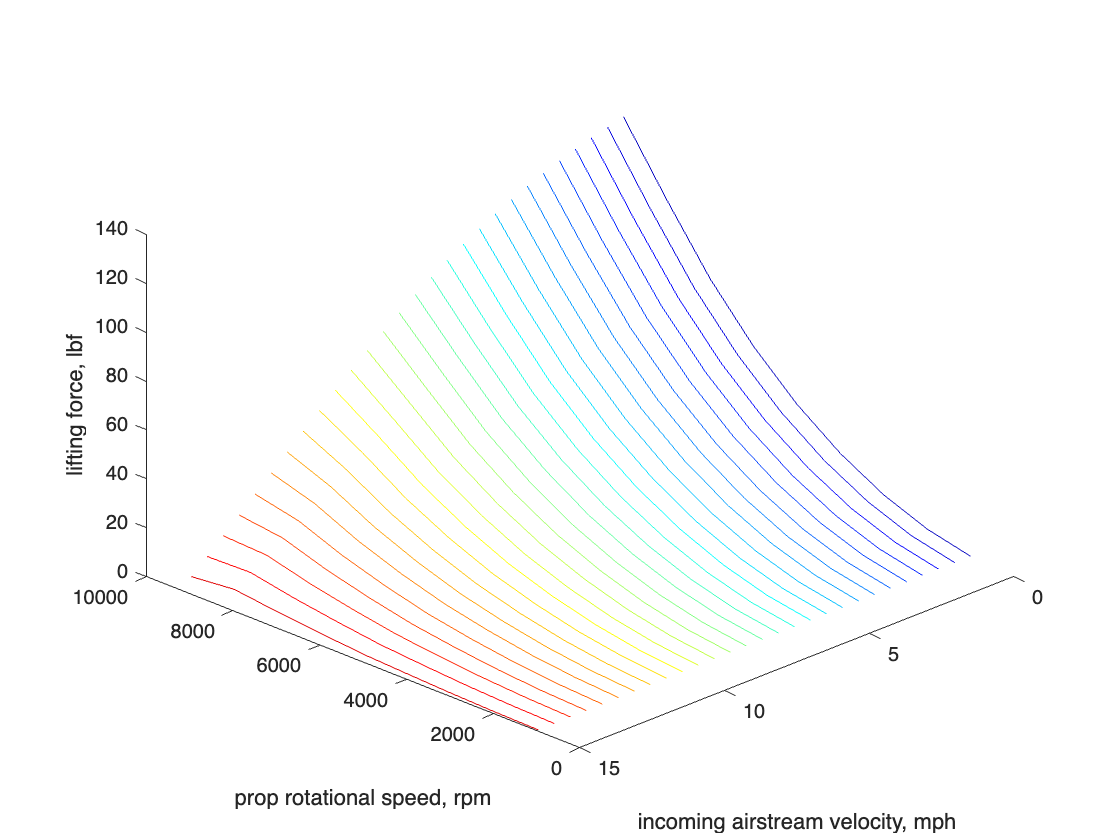

%plots thrust vs. incoming airstream velocity for various RPMs
propplot('PER3_27x13E.dat')

### **Above plot: rpm-incoming airstream velocity-lifting force relationship for a 27 inch diameter 13 inch pitch propellor manufacted by APC Propellors**

For the purposes of designing an optimized quad rotor drone airframe, we decided that looking for data from motor-propellor combinations would be the easiest approach, due to difficulties we ran into in integrating independent data sets from motors and propellors. In our case, we selected the Xoar TA110-20 KV80 motor due to [available data from the Tyto Robotics database](https://database.tytorobotics.com/motors/3gn/xoar-ta110-20-kv80) that indicated it would meet the thrust requirements.

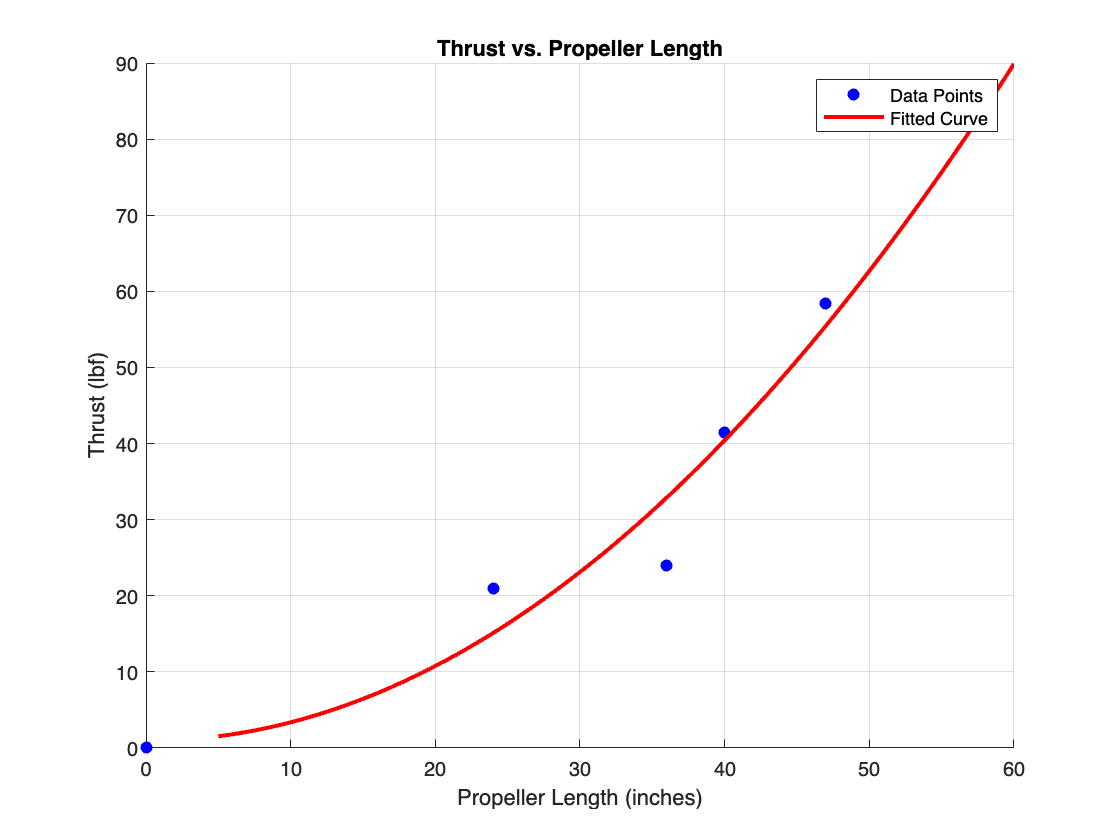

%plotting fitted curve, discrete datapoints, for Xoar TA110-20 KV80 motor combined with various length propellors
thrustvproplen

### **Above plot: Thrust vs. Propellor Length for **Xoar TA110-20 KV80 motor utilizing **various propellors, curve fit**

## Guiding Factors for Airframe Design:

The primary driving factor for the motor arm length is propellor clearance. This is both determined by the fact that the propellors must not overlap to prevent collision of the propellors with each other during operation, but also by the fact that turbulent airflow produced by the propellor tips can impact the performance of the surrounding propellors. We found an [Aviation Stack exchange post](https://aviation.stackexchange.com/questions/22269/how-much-distance-do-i-need-between-quadcopter-propellers-to-avoid-issues) discussing this, stating that leaving a spacing of $\frac{1}{3}$ the diameter of the individual propellor is enough to mitigate it. 

We derived the equation $\mathrm{mininum}\;\mathrm{arm}\;\mathrm{length}=\sqrt{\frac{{\left(\frac{4}{3}\mathrm{prop}\;\mathrm{diameter}\right)}^2 }{2}}$

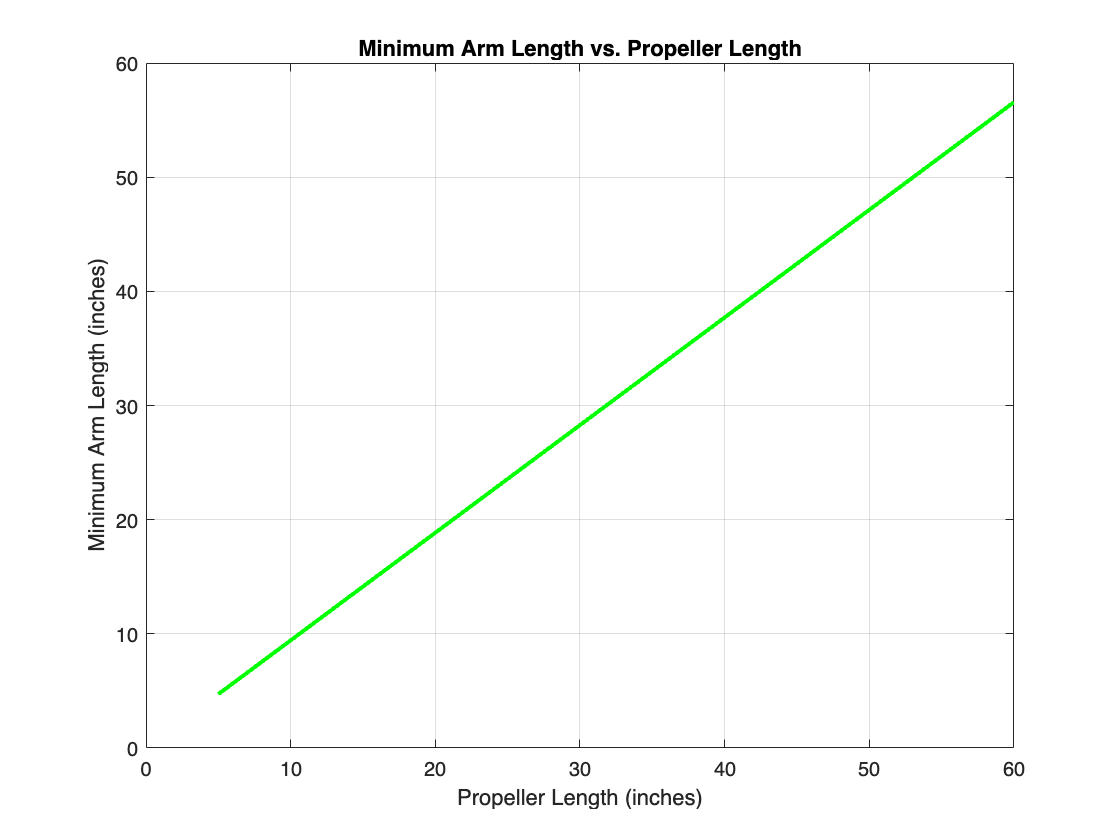

%plotting the minimum arm length, propellor diameter relationship
armvprop

### **Above plot: Minimum Arm Length compared to Propellor length, coming from the minimum arm length equation**

Because we had 4 discrete propellor lengths to choose from (24 inches, 36 inches, 40 inches, 47 inches), we were able to use these values and the above equation for the minimum arm length to calculate the footprint of the airframe. The mounting footprint of the Xoar TA110-20 KV80 motors are a 50mm (~1.9685 inches) diameter circular surface.

The airframe of a large drone like this could easily be manufactured through the machining of a carbon fiber sheet. In order to find the size of this sheet, we derived the equation $\textrm{side}\;\textrm{length}=\cos \left(45\right)*\left(2*\textrm{armlength}+\textrm{motor}\;\textrm{mount}\;\textrm{diameter}\right)$. We ended up selecting the 47 inch diameter propellors for our application as they provided the highest available thrust, giving us the most marging to work within. This led us to find that the airframe could be manufactured from a 54.725 inch square carbon fiber sheet, and we ended up selecting a thickness of 15 mm (~0.5906 inches). 

## Structural Analysis

We wished to do Finite Element Analysis on the 3D model of our airframe but were unable to get access to the PDE toolbox. Instead we chose to simulate the individual arms as fixed beams to understand the shear forces and bending moments under an 0% and 100% thrust load condition.

We wrote a function that takes in the force provided by the motor as an argument in order to calculate and plot the shear force and bending moments the beam will experience for a given loading condition. For the 0% thrust case we input a force of -10.72233 N due to the weight of the motor. For the 100% thrust case we input a force of 259.965 N, corresponding to the 47 inch propellor motor thrust. We simulated the weight of the arm itself, which varies with along its length, as well as two distributed loads of the ESC and battery units. We also utilized Autodesk fusion 360 to make a mockup of the drone arm, using real dimensioning information from our selected parts.

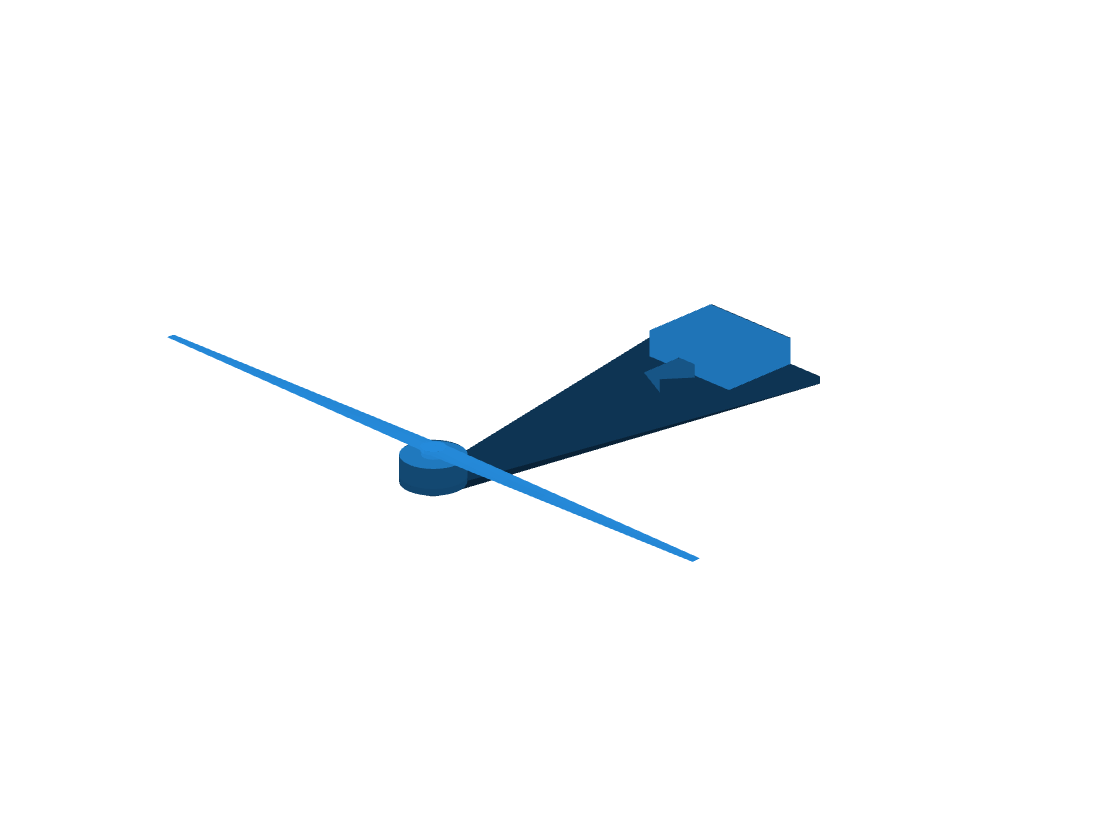

%displays stl of arm mockup
arm

### Above plot: representative arm mockup with motor, ESC, and battery pack pictured

For the shear force and bending moment diagrams, the shear force is plotted in blue and the bending moment is plotted in red.

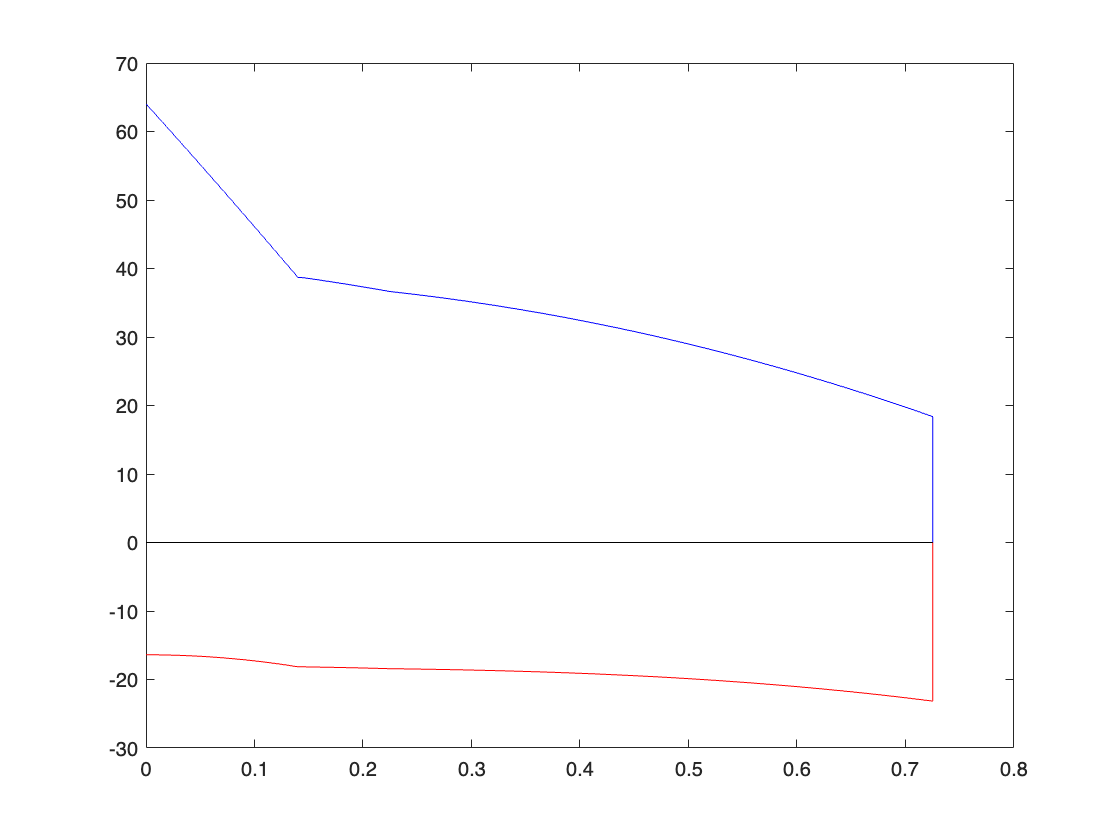

%plots the shear force and bending moment diagram for 0% thrust condition
shearbend(-10.72233)

### Above plot: shear force and bending moment diagram for 0% thrust condition

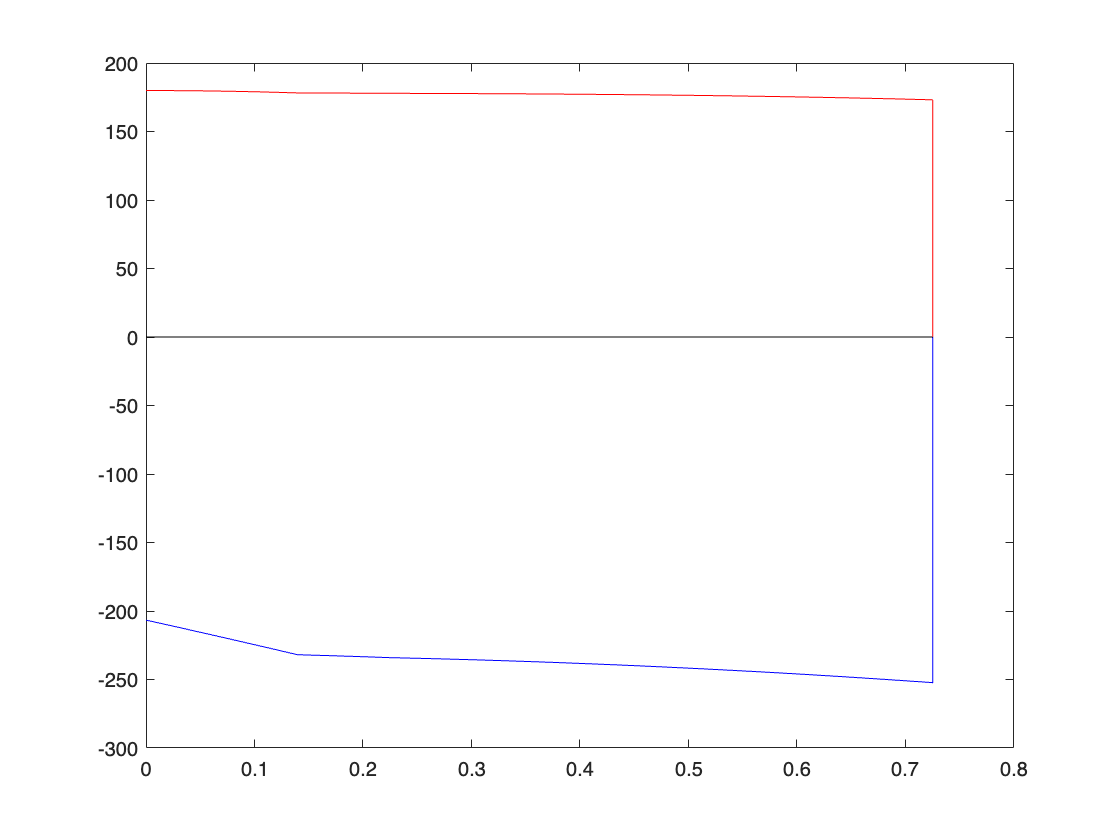

%plots the shear force and bending moment diagram for 100% thrust condition
shearbend(259.965)

### Above plot: shear force and bending moment diagram for 100% thrust condition

## Finalized Design

With all the above information taken into account, we were able to proceed to our final drone mockup. We utilized Autodesk Fusion 360 to create the 3D files and calculate airframe area, in order to calculate total airframe weight and subsequently the total thrust to weight ratio. We intend our drone to carry packages via a slung payload system, which would allow it to lift payloads that are within the weight range but too large to fit directly under the drone. There are some disadvantages to this system, including some difficulties with control scheme, but at the same time it can allow for greater versatility compared to an enclosed payload which may limit overall package size. We implemented a cross bar cutout system in the center of the airframe to enable the mounting of slung payloads.

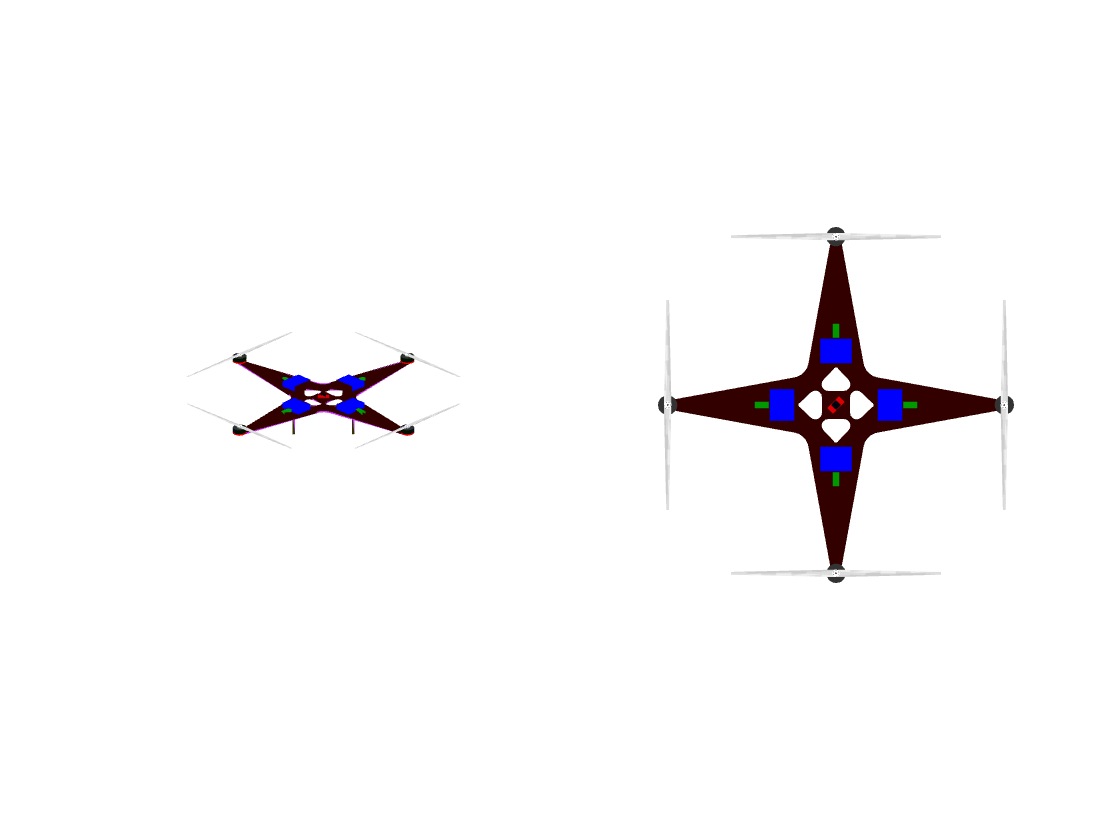

%plots two views of the drone stl
drone

This system is designed to be manufactured from 15mm carbon fiber sheet through computer controlled milling. We calculated the total airframe volume to be 537.07656 cubic inches, and using 0.052 lb/in^3 as the density of the carbon sheet, we found the total airframe mass to be 27.928 lbs. Our total electronics weight came out to be 32.172 lbs, with 22.0991 lbs being contributed from the batteries, 9.1183 lbs from the motors, 0.7937 lbs from the ESCs, and the remaining 0.1609 lbs being from the flight controller. This could be an overly conservative estimate as it does not account for wiring or mounting hardware, but we believe the total unaccounted for weight is less than a pound.

Each motor in this configuration is able to produce 58.4225 lbf of thrust, giving an entire system thrust of 233.69 lbf. The unladen drone weighs 60.1 lbs, so this system thrust gives a maximum theoretical thrust-to-weight ratio of 3.8884. The thrust to weight ratio if the system is carrying a 70 lb load is 1.7962. A paper titled "[Endurance estimation in hovering flight based on battery power requested on quadcopter UAV](https://www.researchgate.net/publication/365620053_Endurance_estimation_in_hovering_flight_based_on_battery_power_requested_on_quadcopter_UAV)," by Richard Octonius and Neno Ruseno, states that a thrust-to-weight ratio between 1.5 and 1.9 for quad rotor UAVs is capable of performance but may have limited endurance in heavy wind, while a thrust-to-weight ratio between 1.9 and 3.0 has strong endurance in heavy wind. They also found a relationship between a overly high thrust-to-weight ratio and lower endurance, which would indicate our system would perform best at moderate to high loads.

 Future work could involve doing finite element analysis on the airframe to further validate that it is strong enough to withstand flight conditions, and potentially further reduce system weight.

### Individual Contributions

This livescript was compiled from code written by Alexander Astorga and Jade Porter. The compliation and writing of this livescript was done by Jade Porter.

### Acknowledgements

This project was made during and for the Engineering Pathways Program MathWorks Summer 2025 Internship.

We are extremely grateful for both this opportunity and the guidance provided by the Mathworks and EPP Team.